# **Finite difference methods to price European Options**

**We start by defining some constant values for an European Call Option**

S0 = 14;      % Start value
K = 15;       % Strike price
r = 0.1;      % Risk free interest rate
sigma = 0.25; % Volatility
T = 0.5;      % Maturity

**Now we discretize the spot sprice and the time, and calculate the theoretical option value given by the Black Scholes equation on the entire grid.**

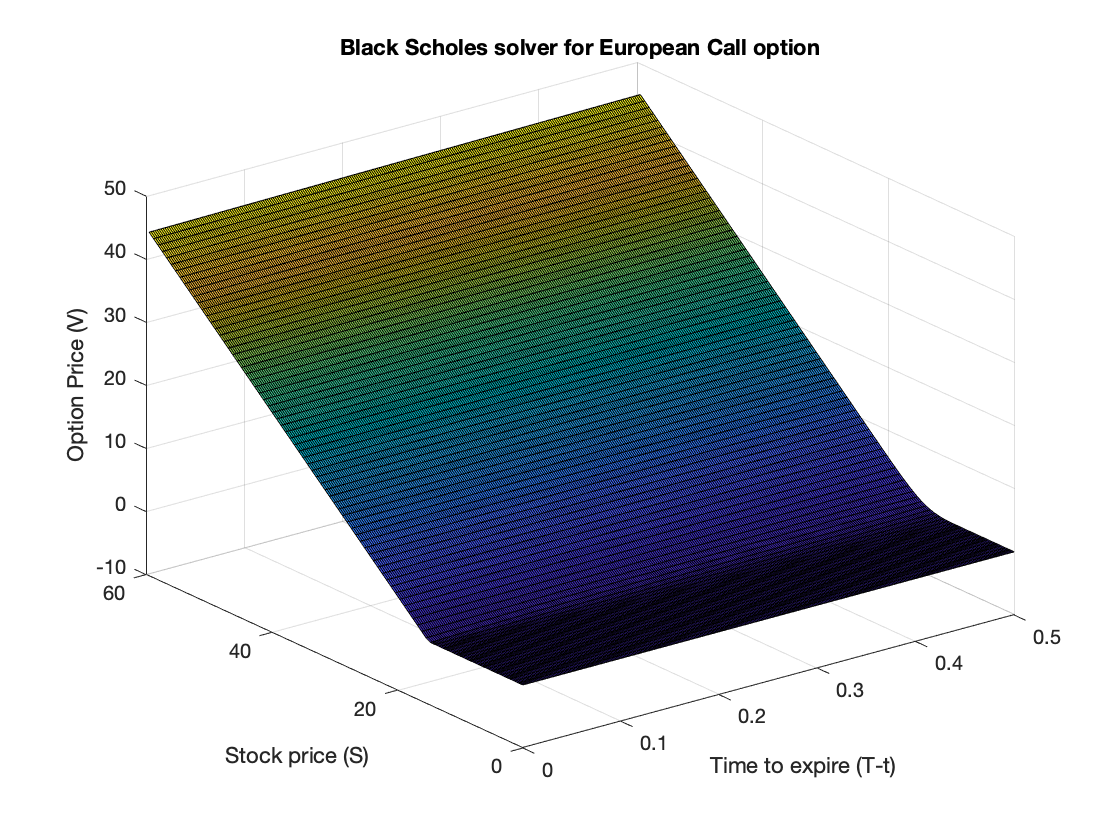

dt = 0.002;
dx = 0.7;

[V_analyti, spat, time] = black_scholes(S0, K, r, sigma, dt, dx, T);
time_to_expire = T-time;

figure(1)
surf(time_to_expire, spat, V_analyti)
xlabel('Time to expire (T-t)'), ylabel('Stock price (S)'), zlabel('Option Price (V)')
title("Black Scholes solver for European Call option");

As we can see the option is worthless when the underlying asset is below the strike price, and we can also observe the time decay. This indicates that this is a correct solution.

## **Finite difference**

**Now we implement both the explicit, and the implicit finite difference methods to price the European Call option.**

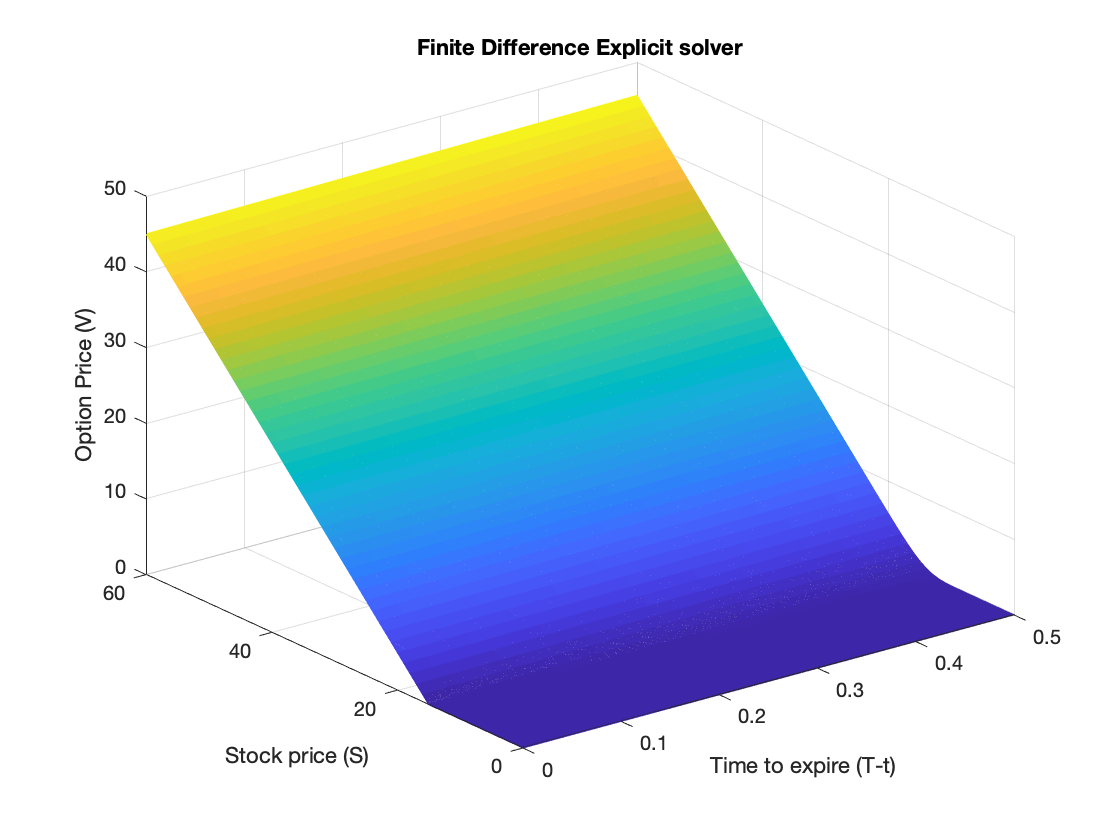

dt = 0.001;
dx = 1;
gamma = 1;

[V_finite_ex, spatial_points_ex, time_points_ex] = CEV_Solver_Explicit(S0,...
    K, T, dt, dx, sigma, r, gamma);
time_to_expire_ex = T-time_points_ex;
[V_finite_im, spatial_points_im, time_points_im] = CEV_Solver_Implicit(S0,...
    K, T, dt, dx, sigma, r, gamma);
time_to_expire_im = T-time_points_im;

figure(2)

mesh(time_to_expire_ex, spatial_points_ex, V_finite_ex);
xlabel('Time to expire (T-t)'), ylabel('Stock price (S)'), zlabel('Option Price (V)')
title("Finite Difference Explicit solver");

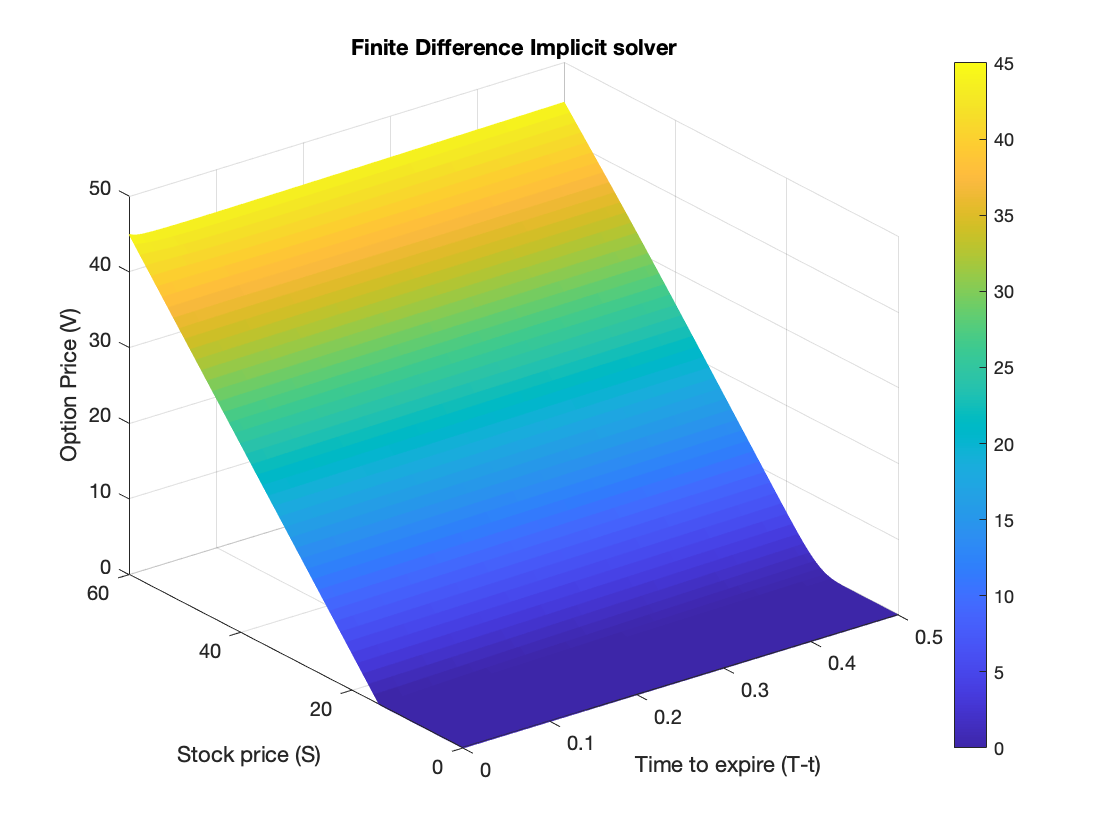


figure(3)

mesh(time_to_expire_im, spatial_points_im, V_finite_im);
colorbar
xlabel('Time to expire (T-t)'), ylabel('Stock price (S)'), zlabel('Option Price (V)')
title("Finite Difference Implicit solver");

As we can see this 3D plot of the option price as a function of time and the stock price is consistent with the solver using the Black Scholes equation.

## Accuracy

Now we want to analyze how the error converges with respect to the time-step and the spatial-step. We use the implicit solver since there is no risk the solution becomes unstable, like the explicit solver can become. This should have no difference, since both the explicit and the implicit solver have the same accuracy: Ordo(dt) + Ordo(dx^2)

We start by analyzing the accuracy with respect to the time step, by creating a vector of time steps and calculating the error using the exact matrix given by the Black Scholes equation.

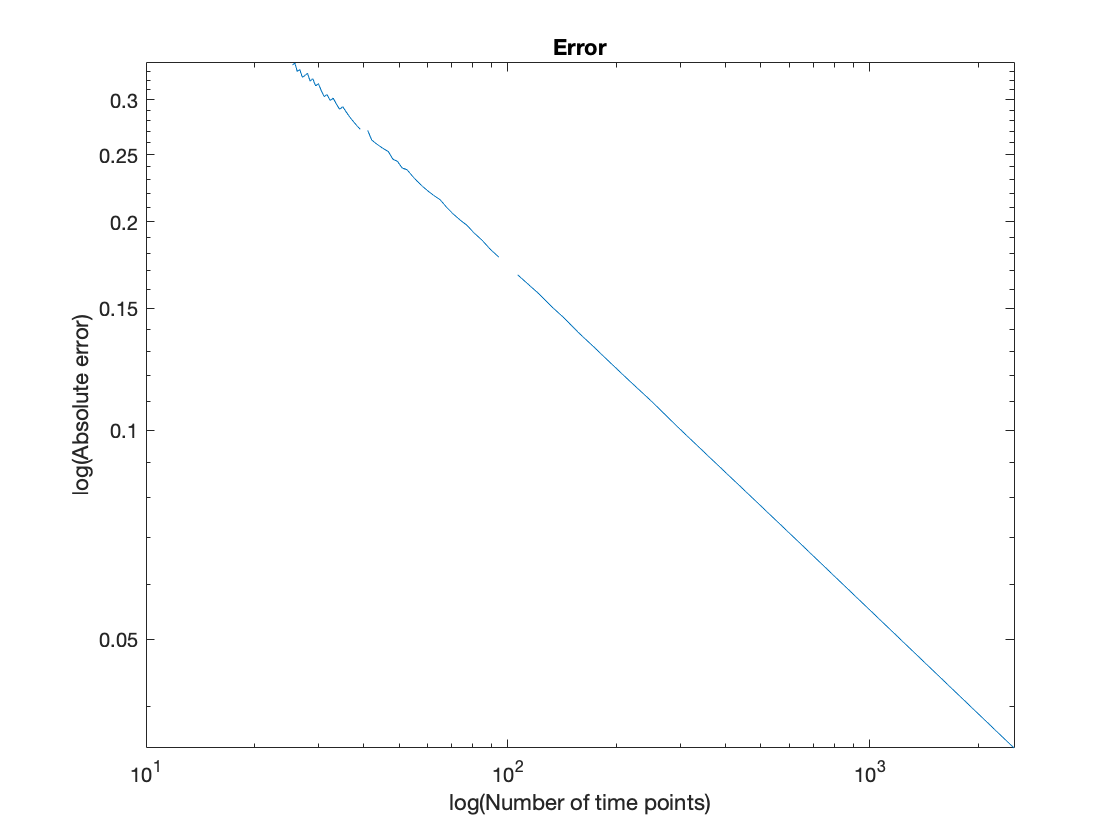

gamma = 1;

dt_samples_vec = 0.02:-0.0003:0.0001; % Array of time steps
dx = 1;

M_vals = zeros(length(dt_samples_vec),1);
err_dt_samples_implicit = zeros(length(dt_samples_vec), 1);

for k = 1:length(dt_samples_vec)
    
    V_analytical = black_scholes(S0, K, r, sigma, ...
        dt_samples_vec(k), dx, T);
    
    V_est_vec_implicit = CEV_Solver_Implicit(S0, K, T,...
        dt_samples_vec(k), dx, sigma, r, gamma);
    
    % Calculate the error
    sum = 0;
    for i = 1:length(V_analytical(1,:))
        for m = 1:length(V_analytical(:,1))
            sum = sum + (V_analytical(m, i) - V_est_vec_implicit(m, i))^2;
        end
    end
    sum = sqrt(sum)/(length(V_analytical(1,: )*length(V_analytical(:,1))));
    err_dt_samples_implicit(k, 1) = sum;
    M_vals(k, 1) = T/dt_samples_vec(k);
   
end
figure(4)
loglog(M_vals(:, 1), err_dt_samples_implicit(:, 1));
xlabel("log(Number of time points)");
ylabel("log(Absolute error)");
title("Error");

Note: when the time step decreases the number of time points increases. As we can see the error converge linear with respect to the number of time steps. This is excpected since the error converge with order Ordo(dt).

Similarily we calculate the accuracy with respect to the spatial step.

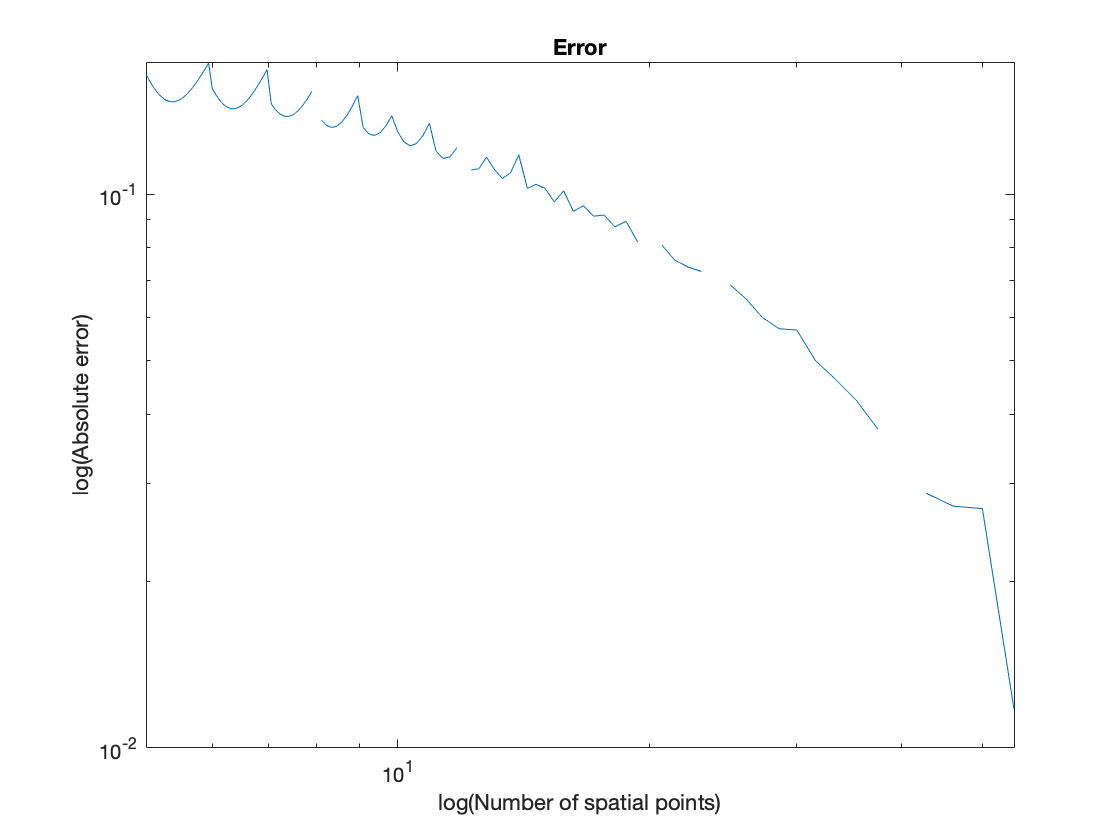

gamma = 1;

dx_samples_vec = 12:-0.1:1;
dt = 0.0001;

N_vals = zeros(length(dx_samples_vec), 1);
err_dx_samples_implicit_2 = zeros(length(dx_samples_vec), 1);

for k = 1:length(dx_samples_vec)
    
    V_analytical_2 = black_scholes(S0, K, r, sigma,...
        dt, dx_samples_vec(k), T);
    
    V_est_vec_implicit_2 = CEV_Solver_Implicit(S0,...
        K, T, dt, dx_samples_vec(k), sigma, r, gamma);

    % Calculate the error
    sum = 0;
    for i = 1:length(V_analytical_2(1,:))
        for m = 1:length(V_analytical_2(:,1))
            sum = sum + (V_analytical_2(m, i) - ...
                V_est_vec_implicit_2(m, i))^2;
        end
    end
    sum = sqrt(sum)/(length(V_analytical_2(1,:)*length(V_analytical_2(:,1))));
    
    err_dx_samples_implicit_2(k, 1) = sum;
    N_vals(k, 1) = 4*K/dx_samples_vec(k);
end

figure(5)
loglog(N_vals(:,1), err_dx_samples_implicit_2);
xlabel("log(Number of spatial points)");
ylabel("log(Absolute error)");
title("Error");

Note: When the spatial step decreases the number of spatial points increases. As we can see the error decreases quadratically, which is excpected since the error converge in the order of Ordo(dx^2) with respect to the spatial step.

## Stability

Now we want to analyze when the explicit finite difference scheme is unstable in regards to a combination of the time-step and the spatial-step. We know the relation:

dt/dx^2 <= lambda, for some constant lambda. We experiment with different x-steps and try to find lambda.

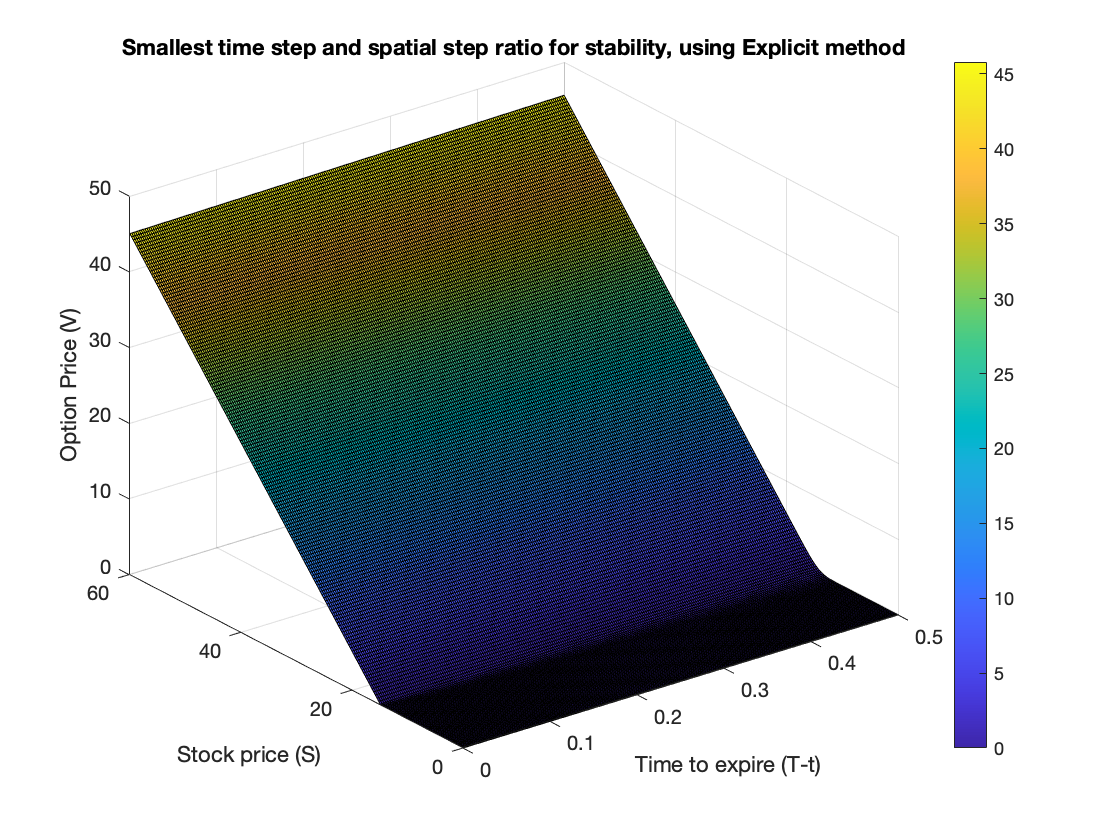

dx_stab1 = 0.3;
dt_stab1 = dx_stab1^(2)*0.024;
gamma = 0.8;

[V_finite_stab1, spatial_points_stab1, time_points_stab1] = ...
    CEV_Solver_Explicit(S0, K, T, dt_stab1, dx_stab1, sigma, r, gamma);
time_to_expire_stab1 = T-time_points_stab1;
figure(6)
surf(time_to_expire_stab1, spatial_points_stab1, V_finite_stab1);
colorbar
xlabel('Time to expire (T-t)'), ylabel('Stock price (S)'), zlabel('Option Price (V)')
title("Smallest time step and spatial step ratio for stability, using Explicit method");


lambda = (dt_stab1)/(dx_stab1^(2));
disp("Lambda = " + lambda);

Lambda = 0.024


We verify that this is the correct lambda, by increasing the time step with 0.0001

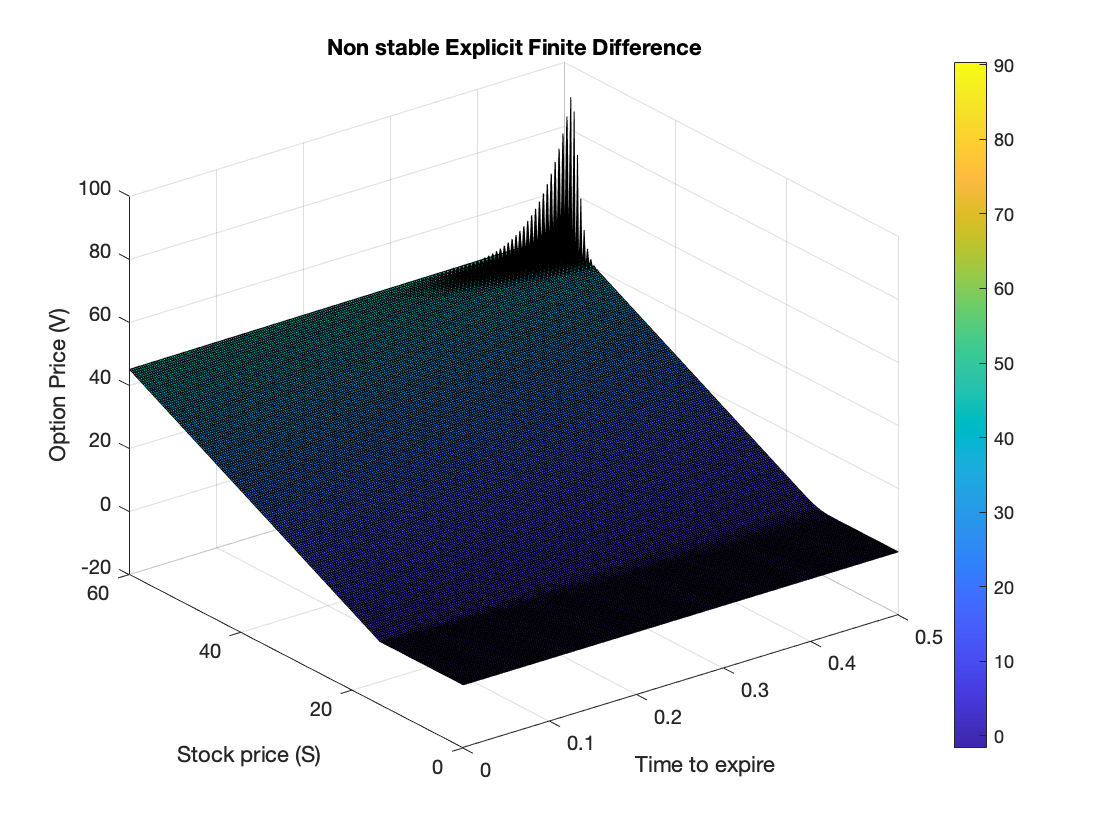

dx_stab2 = dx_stab1;
dt_stab2 = dx_stab2^(2)*lambda + 0.0001;


[V_finite_stab2, spatial_points_stab2, time_points_stab2] = ...
    CEV_Solver_Explicit(S0, K, T, dt_stab2, dx_stab2, sigma, r, gamma);
time_to_expire_stab2 = T-time_points_stab2;
figure(7)
surf(time_to_expire_stab2, spatial_points_stab2, V_finite_stab2);
colorbar
xlabel('Time to expire'), ylabel('Stock price (S)'), zlabel('Option Price (V)')
title("Non stable Explicit Finite Difference");

As we can see, explicit Euler is no longer stable, which indicates that lambda is calculated correctly. If we try to increase the time step again with 0.0001 we get an explosion.

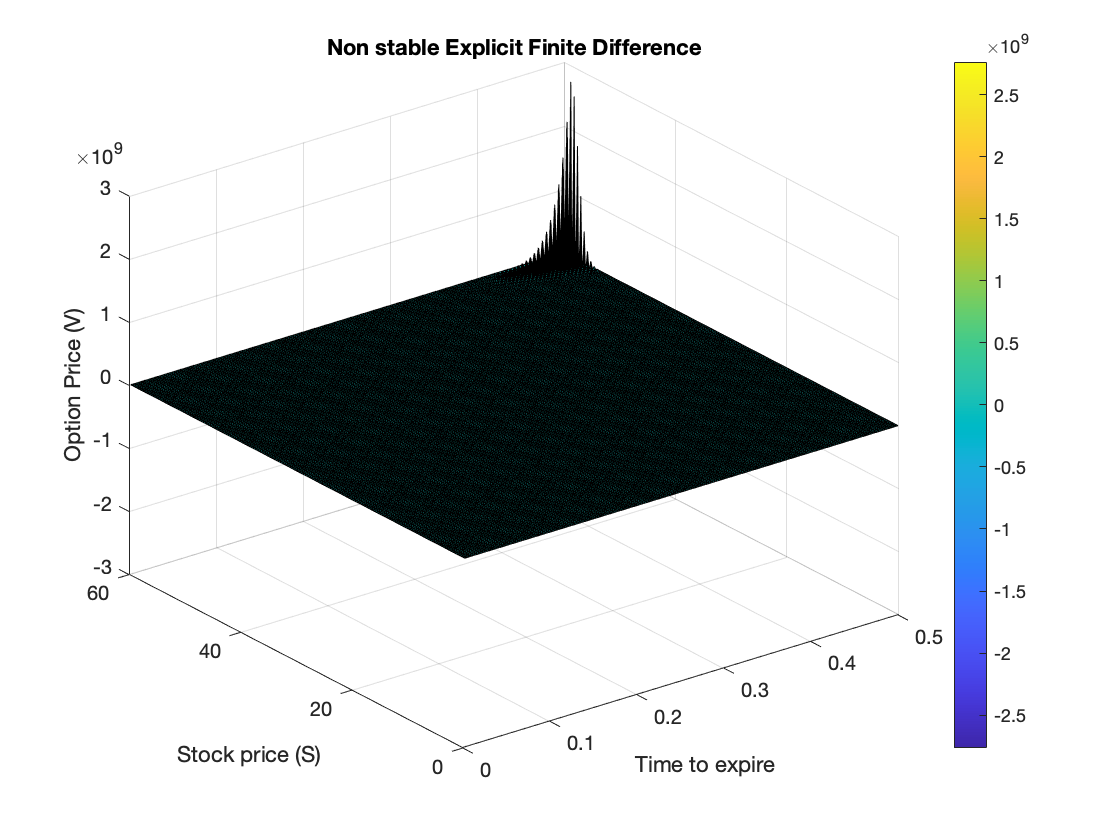

dx_stab3 = dx_stab2;
dt_stab3 = dx_stab3^(2)*lambda + 0.0002;


[V_finite_stab3, spatial_points_stab3, time_points_stab3] = ...
    CEV_Solver_Explicit(S0, K, T, dt_stab3, dx_stab3, sigma, r, gamma);
time_to_expire_stab3 = T - time_points_stab3;

figure(8)
surf(time_to_expire_stab3, spatial_points_stab3, V_finite_stab3);
colorbar
xlabel('Time to expire'), ylabel('Stock price (S)'), zlabel('Option Price (V)')
title("Non stable Explicit Finite Difference");

## Complexity

Now we want to compare the difference between the explicit and the implicit solver with respect to complexity.

We start by analyzing the time complexity with regards to the time step. We create a vector of time steps, and calculate the time the explicit and the implicit solver takes to solve the option price matrix.

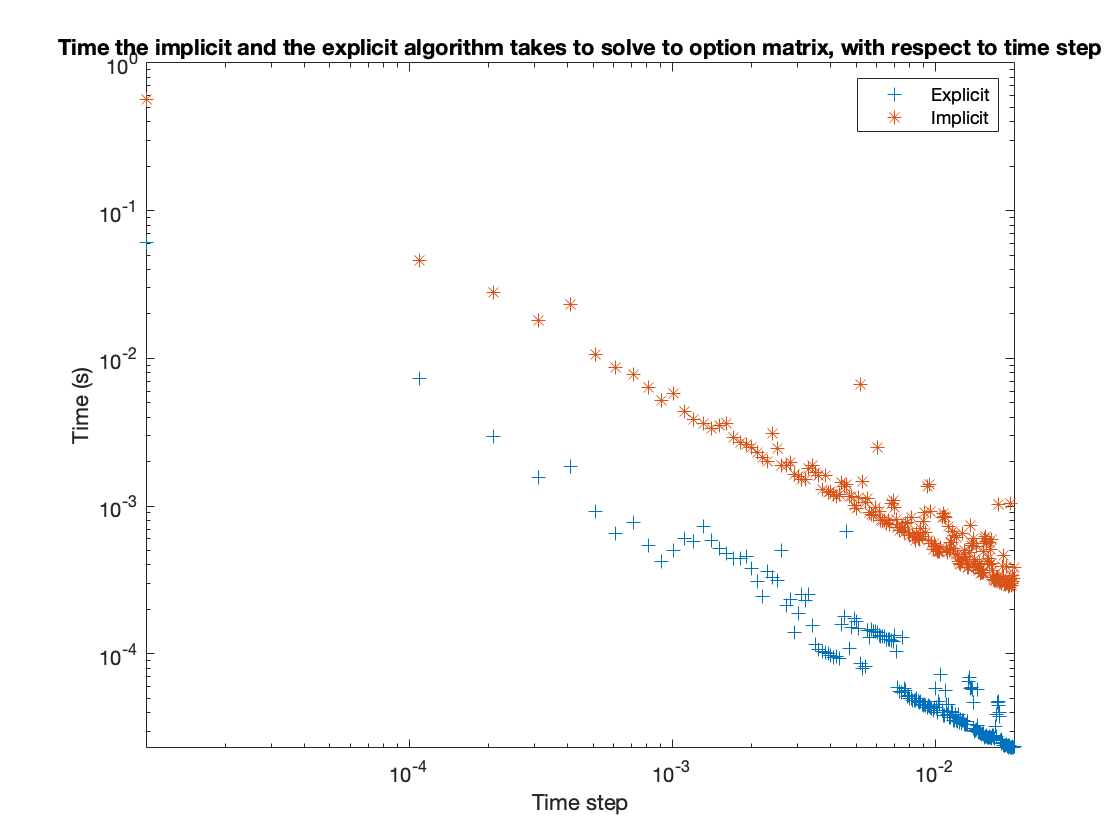

dt_vector_complexity = 0.00001:0.0001:0.02;
time_ex = zeros(length(dt_vector_complexity), 1);
time_im = zeros(length(dt_vector_complexity), 1);

dx = 1;
gamma = 1;

for i = 1:length(dt_vector_complexity)
    tic
    [V_finite_ex_tic, spatial_points_ex_tic, time_points_ex_tic] = ...
        CEV_Solver_Explicit(S0, K, T, dt_vector_complexity(i), dx, sigma, r, gamma);
    
    time_ex(i) = toc;
end

for k = 1:length(dt_vector_complexity)
    tic
    [V_finite_ex_tic, spatial_points_ex_tic, time_points_ex_tic] =...
        CEV_Solver_Implicit(S0, K, T, dt_vector_complexity(k), dx, sigma, r, gamma);
    time_im(k) = toc;
end

figure(9)
loglog(dt_vector_complexity, time_ex, "+", dt_vector_complexity, time_im, "*")
axis([dt_vector_complexity(1) dt_vector_complexity(end) 0 1])
xlabel("Time step")
ylabel("Time (s)")
title("Time the implicit and the explicit algorithm takes to solve to option matrix, with ..." + ...
    "respect to time step")
legend("Explicit", "Implicit")

As we can see explicit solver is faster than the implicit solver with a factor of 10. We can also see from the plot that the time complexity of the algorithms with respect to time step, is of the order: Ordo(log(dt)). We can also see that as the time step becomes larger, the time the algorithm takes to solve the option matrix, decreases, which is excpected since the number of computations decreases.

Similarily we analyze the time complexity with respect to the spatial step.

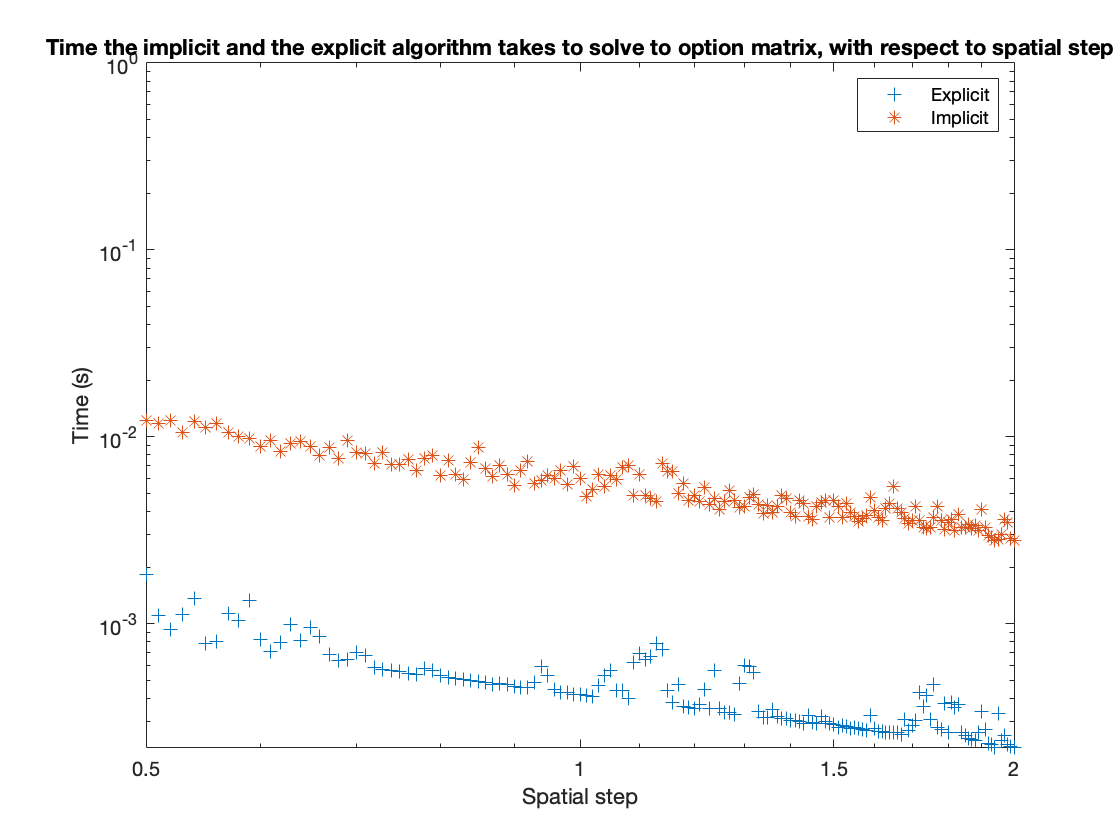

dx_vector_complexity = 0.5:0.01:2;
time_ex_x = zeros(length(dx_vector_complexity), 1);
time_im_x = zeros(length(dx_vector_complexity), 1);

dt = 0.001;
gamma = 1;
for i = 1:length(dx_vector_complexity)
    tic
    [V_finite_ex_tic_2, spatial_points_ex_tic_2, time_points_ex_tic_2] =...
        CEV_Solver_Explicit(S0, K, T, dt, dx_vector_complexity(i), sigma, r, gamma);
    
    time_ex_x(i) = toc;
 
end

for k = 1:length(dx_vector_complexity)
    tic
    [V_finite_ex_tic_2, spatial_points_ex_tic_2, time_points_ex_tic_2] =...
        CEV_Solver_Implicit(S0, K, T, dt, dx_vector_complexity(k), sigma, r, gamma);
    time_im_x(k) = toc;
end

figure(10)
loglog(dx_vector_complexity, time_ex_x, "+", dx_vector_complexity, time_im_x, "*")
axis([dx_vector_complexity(1) dx_vector_complexity(end) 0 1])
xlabel("Spatial step")
ylabel("Time (s)")
title("Time the implicit and the explicit algorithm takes to solve to option matrix, with ..." + ...
    "respect to spatial step")
legend("Explicit", "Implicit")

As we can see explicit solver is faster than the implicit solver with a factor of 10. We can also see from the plot that the time complexity of the algorithms with respect to spatial step, is of the order: Ordo(log(dt)). We can also see that as the spatial step becomes larger, the time the algorithm takes to solve the option matrix, decreases, which is excpected since the number of computations decreases

## Gamma

Now we analyze how the computed price changes when we change gamma. Gamma controls the relationship between volatility and price, and is the central feature of the CEV model.

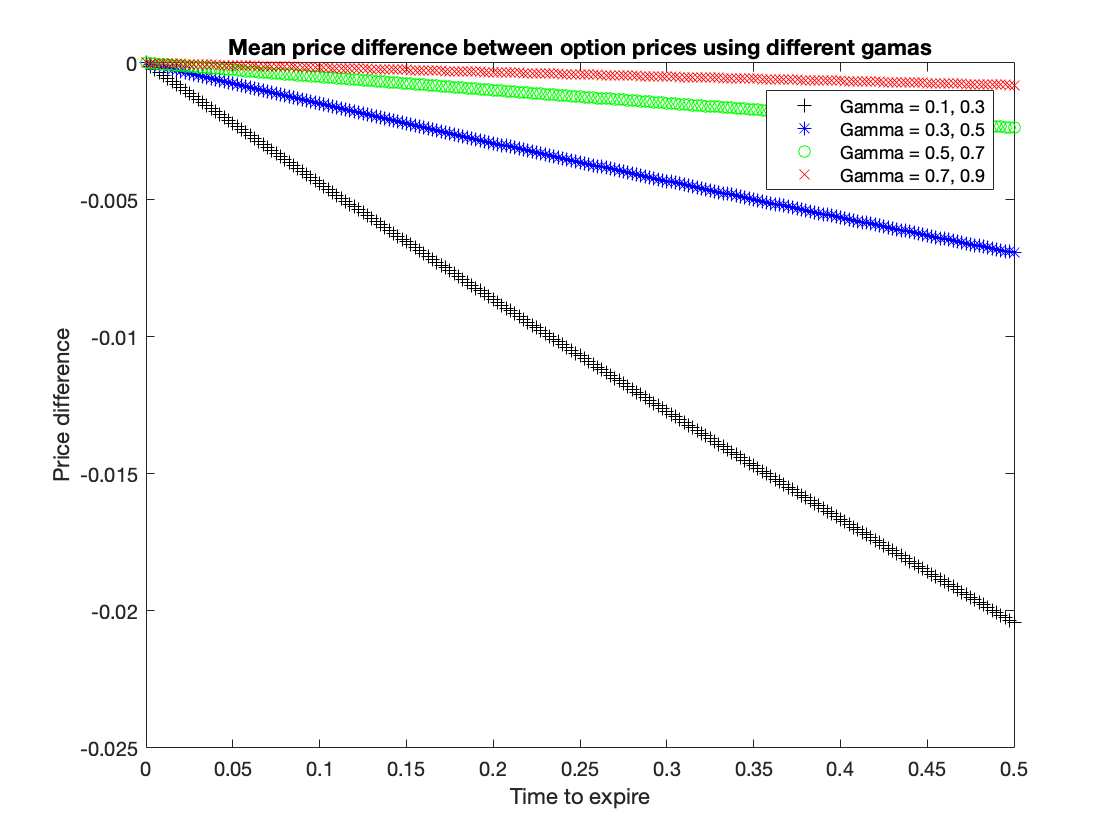

dt = 0.0025;
dx = 0.5;

gamma1 = 0.1;
gamma2 = 0.3;
gamma3 = 0.5;
gamma4 = 0.7;
gamma5 = 0.9;

[V_finite_gamma1, spatial_points_gamma1, time_points_gamma1] = ...
    CEV_Solver_Explicit(S0, K, T, dt, dx, sigma, r, gamma1);
[V_finite_gamma2, spatial_points_gamma2, time_points_gamma2] = ...
    CEV_Solver_Explicit(S0, K, T, dt, dx, sigma, r, gamma2);
[V_finite_gamma3, spatial_points_gamma3, time_points_gamma3] = ...
    CEV_Solver_Explicit(S0, K, T, dt, dx, sigma, r, gamma3);
[V_finite_gamma4, spatial_points_gamma4, time_points_gamma4] = ...
    CEV_Solver_Explicit(S0, K, T, dt, dx, sigma, r, gamma4);
[V_finite_gamma5, spatial_points_gamma5, time_points_gamma5] = ...
    CEV_Solver_Explicit(S0, K, T, dt, dx, sigma, r, gamma5);

diff54 = mean(V_finite_gamma4(:, :) - V_finite_gamma5(:, :));
diff43 = mean(V_finite_gamma3(:, :) - V_finite_gamma4(:, :));
diff32 = mean(V_finite_gamma2(:, :) - V_finite_gamma3(:, :));
diff21 = mean(V_finite_gamma1(:, :) - V_finite_gamma2(:, :));

figure(11)

plot(T - time_points_gamma5, diff54, 'k+', T - time_points_gamma4, diff43, 'b*', ...
    T - time_points_gamma5, diff32, 'go', T - time_points_gamma5, diff21, 'rx');

ylabel("Price difference");
xlabel("Time to expire");
title("Mean price difference between option prices using different gamas");

prompt54 = "Gamma = " + gamma4 + ", " + gamma5;
prompt43 = "Gamma = " + gamma3 + ", " + gamma4;
prompt32 = "Gamma = " + gamma2 + ", " + gamma3;
prompt21 = "Gamma = " + gamma1 + ", " + gamma2;

legend(prompt21, prompt32, prompt43, prompt54, [440 350 0.15 0.0869]);

We can see from the plot, that there is a price difference when using different gammas. When gamma gets larger the price goes down. 

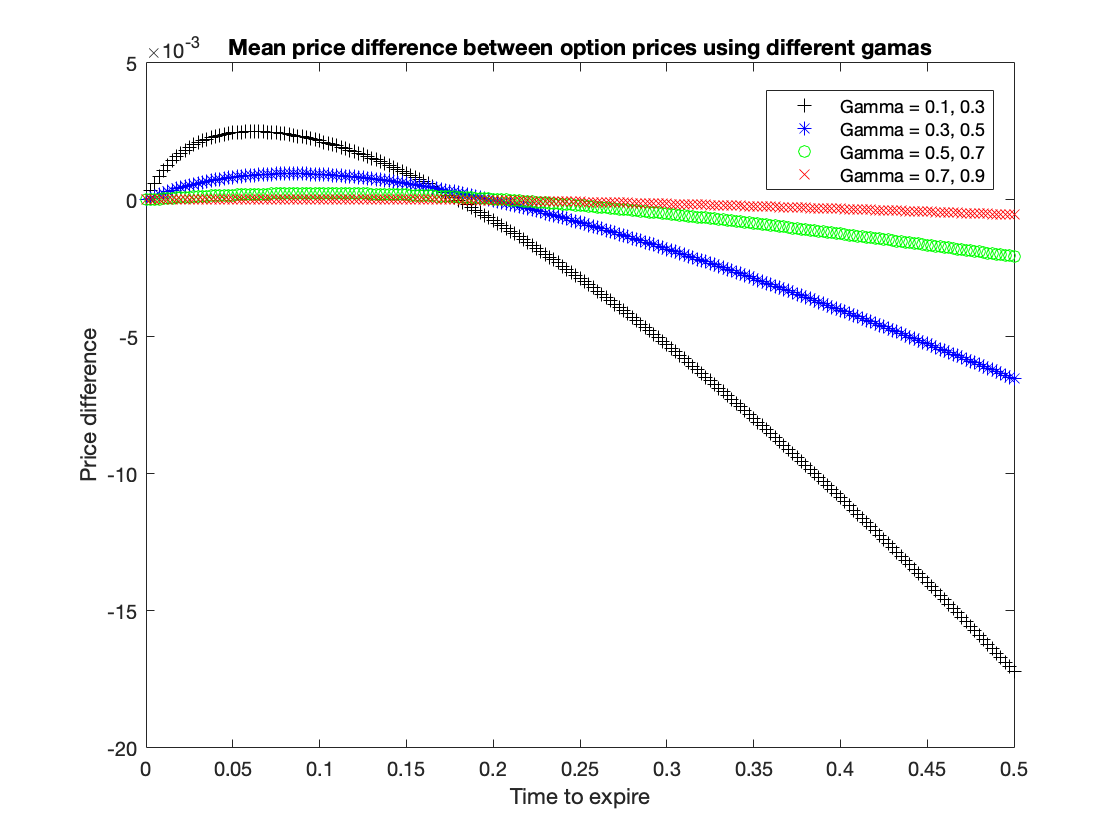

dt = 0.0025;
dx = 0.5;

gamma1_im = 0.1;
gamma2_im = 0.3;
gamma3_im = 0.5;
gamma4_im = 0.7;
gamma5_im = 0.9;

[V_finite_gamma1_im, spatial_points_gamma1_im, time_points_gamma1_im] = ...
    CEV_Solver_Implicit(S0, K, T, dt, dx, sigma, r, gamma1_im);
[V_finite_gamma2_im, spatial_points_gamma2_im, time_points_gamma2_im] = ...
    CEV_Solver_Implicit(S0, K, T, dt, dx, sigma, r, gamma2_im);
[V_finite_gamma3_im, spatial_points_gamma3_im, time_points_gamma3_im] = ...
    CEV_Solver_Implicit(S0, K, T, dt, dx, sigma, r, gamma3_im);
[V_finite_gamma4_im, spatial_points_gamma4_im, time_points_gamma4_im] = ...
    CEV_Solver_Implicit(S0, K, T, dt, dx, sigma, r, gamma4_im);
[V_finite_gamma5_im, spatial_points_gamma5_im, time_points_gamma5_im] = ...
    CEV_Solver_Implicit(S0, K, T, dt, dx, sigma, r, gamma5_im);

diff54_im = mean(V_finite_gamma4_im(:, :) - V_finite_gamma5_im(:, :));
diff43_im = mean(V_finite_gamma3_im(:, :) - V_finite_gamma4_im(:, :));
diff32_im = mean(V_finite_gamma2_im(:, :) - V_finite_gamma3_im(:, :));
diff21_im = mean(V_finite_gamma1_im(:, :) - V_finite_gamma2_im(:, :));

figure(12)

plot(T - time_points_gamma5_im, diff54_im, 'k+', T - time_points_gamma4_im, diff43_im, 'b*',...
    T - time_points_gamma5_im, diff32_im, 'go', T - time_points_gamma5_im, diff21_im, 'rx');

ylabel("Price difference");
xlabel("Time to expire");
title("Mean price difference between option prices using different gamas");

prompt54_im = "Gamma = " + gamma4_im + ", " + gamma5_im;
prompt43_im = "Gamma = " + gamma3_im + ", " + gamma4_im;
prompt32_im = "Gamma = " + gamma2_im + ", " + gamma3_im;
prompt21_im = "Gamma = " + gamma1_im + ", " + gamma2_im;

legend(prompt21_im, prompt32_im, prompt43_im, prompt54_im, [440 350 0.15 0.0869]);

 We can see from the plot, that there is a price difference when using different gammas. When gamma gets larger the price goes down. 

## Helper functions

function [V, spatial_points, time_points] = CEV_Solver_Explicit(S0, K, T, dt, dx, sigma, r, gamma) 
% S0    - Start price
% K     - Strike price
% T     - Maturity
% SMAX  - Maximal S value
% dt    - Time step
% dx    - Spatial step
% sigma - Volatility
% r     - Risk free interest rate
% gamma - Controls the relationship between volatility and price

    SMIN = 0;
    SMAX = 4*K;
    
    % Discretisize the spot price, and the time
    time_points = 0:dt:T;
    spatial_points = SMIN:dx:SMAX;
    
    V = zeros(length(spatial_points), length(time_points)); % Solution matrix
    
    % We start by settings some boundary conditions
    
    % Final time point
    for i = 1:length(spatial_points)
        % Pay off function
        V(i, length(time_points)) = max(spatial_points(i)-K,0);
    end
    % Start time point
    for k = 1:length(spatial_points)
        V(i, 1) = 0;
    end

    
    for n = length(time_points):-1:2 % Time levels
        % Set boundary conditions
        V(1, n-1) = 0;
        V(length(spatial_points), n-1) = SMAX -K*exp(-r*(T-time_points(n-1)));
        for j = 2:length(spatial_points)-1 % Spatial
            % Finite difference scheme
            V(j, n-1) = V(j, n) + (sigma^(2) * 0.5 * dt * spatial_points(j)^(2*gamma))/...
                (dx^(2)) * ...
                (V(j+1, n) - 2*V(j, n) + V(j-1, n)) + ...
                (dt * r * spatial_points(j) * (V(j+1, n) - V(j-1, n)) * 0.5)/(dx) - ...
                r * dt * V(j,n);
        end
    end
end

function [V, spatial_points, time_points] = CEV_Solver_Implicit(S0, K, T, dt, dx,...
    sigma, r, gamma) 
% S0    - Start price
% K     - Strike price
% T     - Maturity
% SMAX  - Maximal S value
% dt    - Time step
% dx    - Spatial step
% sigma - Volatility
% r     - Risk free interest rate
% gamma - Controls the relationship between volatility and price

    SMIN = 0;
    SMAX = 4*K;
    
    % Discretisize the spot price, and the time
    time_points = 0:dt:T;
    spatial_points = SMIN:dx:SMAX;
    
    V(length(spatial_points), length(time_points)) = nan; % Solution matrix
    
    % We start by settings some boundary conditions
    
    % Final time point
    for i = 1:length(spatial_points)
        % Pay off function
        V(i, length(time_points)) = max(spatial_points(i)-K,0);
    end
    % Start time point
    for k = 1:length(spatial_points)
        V(i, 1) = 0;
    end
    
    % Final and start spot price
    for n = 1:length(time_points)
        V(1, n) = 0;
        V(length(spatial_points), n) = SMAX - K*exp(-r*(T-time_points(n)));
    end

    % Create matrices
    ax = 0.5 * (r * dt * spatial_points - sigma^(2) * dt * ...
        (spatial_points.^(2*gamma)));
    bx = 1 + sigma^(2) * dt * spatial_points.^(2*gamma)...
        + r * dt;
    cx = -0.5 * (r * dt * spatial_points + sigma^(2) * dt * ...
        (spatial_points.^(2*gamma)));
    
    B = diag(ax(3:length(spatial_points)), -1) + diag(bx(2:length(spatial_points))) + ... 
    diag(cx(2:length(spatial_points)-1),1);
    
    [L, U] = lu(B); % lu factorization
    
    lost = zeros(size(B,2) ,1);
    
    for i = length(time_points)-1:-1:1 % Propagate backwards in time
        lost(1) = -ax(2) * V(1, i); 
        lost(end) = -cx(end) * V(end, i); 
        if length(lost) == 1
            lost = -ax(2) * V(1 , i) - cx(end) * V(end , i);
        end
        V(2:length(spatial_points),i) = U \ (L \ (V(2:length(spatial_points),i+1) ...
            + lost)); 
    end
end

function sol = bsexact(sigma, r, E, T, s)
    % sigma: volatilitet
    % r:     riskfri ränta
    % E:     Strike price
    % T:     Maturity
    % s:     Priset på den underliggande tillgången
    
    d1 = ( log(s/E) + (r + 0.5*sigma^2)*T )/(sigma*sqrt(T));
    d2 = d1 - sigma*sqrt(T);
    F = 0.5*s*(1+erf(d1/sqrt(2))) - exp(-r*T)*E*0.5*(1+erf(d2/sqrt(2)))';
    sol = F;
end

function [exact, spatial_points, time_points] = black_scholes(S0, K, r, sigma,...
    dt, dx, T)

    SMAX=4*K;
    time_points = 0:dt:T; %time 
    spatial_points = 0:dx:SMAX; %price of the underlying
    
    exact = zeros(length(spatial_points), length(time_points));
    
    % Calculate the black scholes value on the entire grid
    for n = 1:length(time_points) % All the time points
        for i = 1:length(spatial_points) % All the spot prices
            exact(i, n) = bsexact(sigma, r, K, T-time_points(n), spatial_points(i));
        end
    end
end